## 1 单缝

(22.76 + 23.43)/2

ans = 23.0950

deg2rad((22.76 + 23.43)/2)

ans = 0.4031


global a b lambda_theo b_SingleSlit
a = 8.5;
b = 3.5;
b_SingleSlit = 8;
lambda_theo = 3.1892;
k_theo = 2*pi/lambda_theo;

lambda_exp = b_SingleSlit*sind(23.095)

lambda_exp = 3.1381

eta = (lambda_exp - lambda_theo)./lambda_theo*100

eta = -1.6037

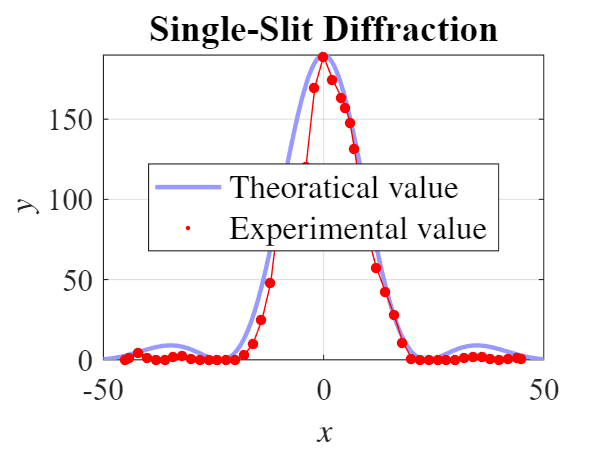


I_theo = @(theta) 190 * (  sin(0.5*k_theo*b_SingleSlit*sin(theta)) ./ (0.5*k_theo*b_SingleSlit*sin(theta))  ).^2;
theta_deg_array = [linspace(-50, -0.001, 100), linspace(0.001, 50)];
%theta_array = deg2rad(theta_deg_array);
stc = MyPlot(theta_deg_array, I_theo(deg2rad(theta_deg_array)));


theta_deg_array = [
0	2	4	5	6	7	8	9	10	12	14	16	18	20	22	24	26	28	30	32	34	36	38	40	42	44	45    
];
theta_deg_array = [-theta_deg_array(end:-1:1), theta_deg_array];
U_positive = [
189.2	175	163.8	157.5	147.9	131.6	112.3	93.7	77.5	57.4	42.5	28.1	10.8	1.1	0.1	0	0.1	0.2	0.3	1.3	2.2	2	0.5	0.2	1.0	1.3	0.8
];
U_negtive = [
189.2	170	120.6	107.6	108.5	112.9	112.0	107.4	94.1	48.3	24.9	10.3	3.0	0.2	0.0	0.0	0.0	0.1	0.9	2.9	2.3	0.3	0.0	1.7	4.7	1.7	0.3
];
U_negtive = U_negtive(end:-1:1); % 转换为 -50 deg 开始
I = [U_negtive, U_positive];

sca = MyScatter_ax(stc.axes, theta_deg_array, I);
sca.scatter.scatter_1.SizeData = 200;
sca.scatter.scatter_1.MarkerEdgeColor = 'r';
stc.label.y.String = '$U$ (mV)';
stc.label.x.String = '$\theta\ (^\circ)$';
stc.axes.Title.String = "Single-Slit Diffraction";

stc2 = MyPlot_ax(stc.axes, theta_deg_array, I);
stc2.plot.plot_1.LineWidth = 0.3;
stc2.plot.plot_1.Color = 'r';

stc.leg.String = ["Theoratical value"; "Experimental value"];

%MyExport_pdf_docked

## 2 双缝

global a b lambda 
% 注意这些物理量的单位都是 cm !
lambda = 3.1915

lambda = 3.1915

a = 8.5;
b = 3.5;

x1 = (11.43 + 9.58)*0.5

x1 = 10.5050

x2 = (22.39 + 20.58)*0.5

x2 = 21.4850

x3 = (32.41 + 31.60)*0.5

x3 = 32.0050

lambda1 = a*sind(x1)/0.5

lambda1 = 3.0995

lambda2 = a*sind(x2)/1

lambda2 = 3.1132

lambda3 = a*sind(x3)/1.5

lambda3 = 3.0033


lambda_exp = [
    lambda1
    lambda2
    lambda3
];
eta = (lambda_exp - lambda_theo)./lambda_theo*100

eta =    -2.8138
   -2.3834
   -5.8292



lambda_exp = mean(lambda_exp)

lambda_exp = 3.0720

eta = (lambda_exp - lambda_theo)./lambda_theo*100

eta = -3.6754

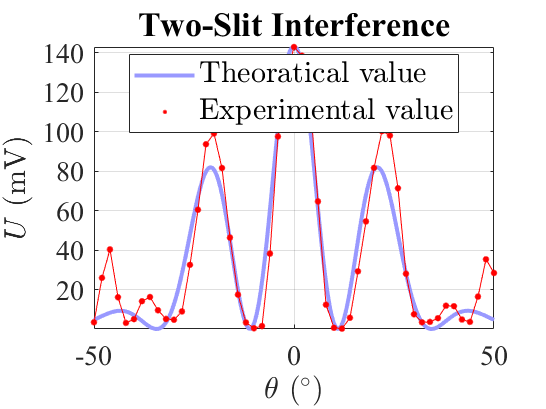


sinc = @(x) sin(x)./x;
alpha = @(theta) pi*a/lambda*sin(theta);
beta = @(theta) pi*b/lambda*sin(theta);
I_theo = @(theta) 142.8*sinc(beta(theta)).^2 .* cos(alpha(theta)).^2;

theta_deg_array = [linspace(-50, -0.001, 100), linspace(0.001, 50, 100)];
stc = MyPlot(linspace(-50, 50, 200), I_theo(deg2rad(theta_deg_array)));

U_negtive = [
142.8	126.8	97.5	38.2	1.5	0.4	3.3	17.4	46.3	81.5	99	93.6	60.4	32.5	8.9	4.7	5.1	9.5	16.2	14.1	5	3.1	16.1	40.3	25.9	3.4
];
U_negtive = U_negtive(end:-1:1); % 转换为 -50 deg 开始
U_positive = [
142.8	138.4	116.3	64.6	12.3	0.6	0.2	5.7	29.2	54.5	81.6	100.2	98	71.3	28	7.5	3.4	3.6	5.5	11.8	11.6	4.8	3.6	16.4	35.3	28.4    
];
theta_deg_array = [-50:2:0, 0:2:50];
%theta_rad_array = deg2rad(theta_deg_array);
I_exp = [U_negtive, U_positive];

sca = MyScatter_ax(stc.axes, theta_deg_array, I_exp);
sca.scatter.scatter_1.MarkerEdgeColor = 'r';

stc2 = MyPlot_ax(stc.axes, theta_deg_array, I_exp);
stc2.plot.plot_1.LineWidth = 0.3;
stc2.plot.plot_1.Color = 'r';

stc2 = MyPlot_ax(stc.axes, theta_deg_array, I_exp);
stc2.plot.plot_1.LineWidth = 0.3;
stc2.plot.plot_1.Color = 'r';

stc.label.y.String = '$U$ (mV)';
stc.label.x.String = '$\theta\ (^\circ)$';
stc.axes.Title.String = "Two-Slit Interference";
stc.leg.String = ["Theoratical value"; "Experimental value"];


%MyExport_pdf_docked

## 3 迈克尔逊干涉

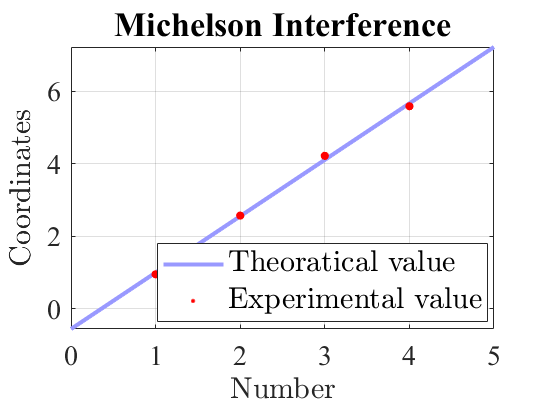

X = [
1
2
3
4
];
Y = [
0.95
2.57
4.22
5.59
];

stc = MyPlot(0:0.05:5, fittedmodel(0:0.05:5)');
sca = MyScatter_ax(stc.axes, X', Y');
sca.scatter.scatter_1.MarkerEdgeColor = 'r';
sca.scatter.scatter_1.SizeData = 200;
sca.axes.Title.String = 'R^2 = 0.9983, RMSE = 0.1011';
stc.label.x.String = 'Number';
stc.label.y.String = 'Coordinates';
stc.axes.Title.String = "Michelson Interference";
stc.leg.String = ["Theoratical value"; "Experimental value"];

%MyExport_pdf_docked

lambda_exp = 1.5575*2

lambda_exp = 3.1150

eta = (lambda_exp - lambda_theo)./lambda_theo*100

eta = -2.3266

## 4 布拉格衍射

d = 4

d = 4

beta = 68.62;
lambda_exp = 2*d*cosd(beta)

lambda_exp = 2.9164

eta = (lambda_exp - lambda_theo)./lambda_theo*100

eta = -8.5534


d = 2*sqrt(2)

d = 2.8284

beta = 54.43

beta = 54.4300

lambda_exp = 2*d*cosd(beta)

lambda_exp = 3.2906

eta = (lambda_exp - lambda_theo)./lambda_theo*100

eta = 3.1787